# A Poisson problem with homogeneous vertex conditions

Set up a quantum graph in the form of a lollipop

Solve the vertex-value problem 


$$\triangle u = f \\
u'(\mathtt{v_1}) = 0 \\
\sum u'(\mathtt{v_2}) = 0$$


where 

- The functions on the right-hand-sides are $f = \left\{ -\pi^2\cos(\pi x), -4\cos(2x) \right\}$on the two edges.

- the edges have lengths $\left\{
2, 2\pi
\right\}$.

- The exact solutions on the edges are $\left\{
c+\cos(\pi x), c+\cos(2x)
\right\}$.

Exact solution computed in accompanying Mathematica notebook of the same name.

## Quantum graph definition

tag = 'nbell';
robinCoeff=[0 0];

## The exact solution

u1=@(x) cos(pi*x);
u2=@(x) cos(2*x);

## The right hand sides

Edges and nodes

f1=@(x) -pi^2*cos(pi*x);
f2=@(x) -4*cos(2*x);
nodeData = [0; 0];

## Solve the system twice,

doubling the number of discretization points between the two runs.

nx = [16 32];
errors=zeros(1,2);
for k=1:2

Define the quantum graph (all that changes between the two iterates is the number of discretization points per unit length).

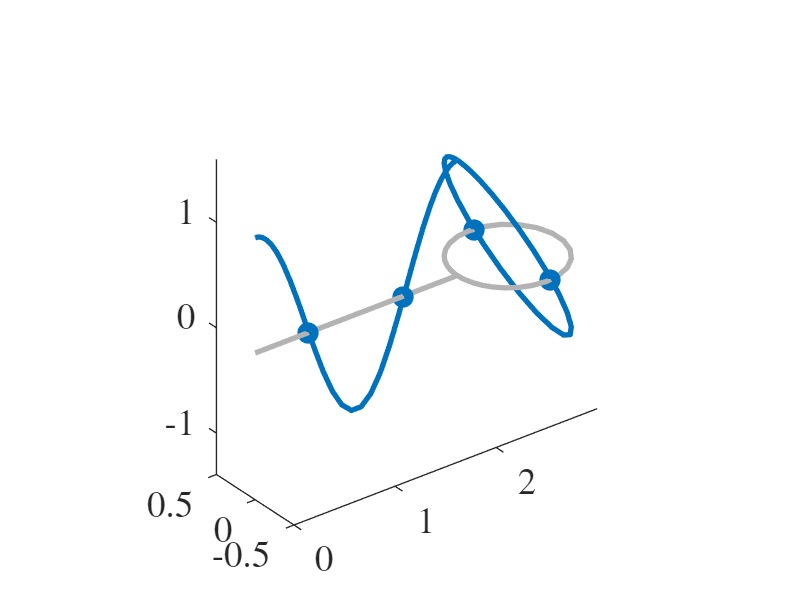

    Phi=quantumGraphFromTemplate(tag,'RobinCoeff',robinCoeff,'nx',nx(k),'Discretization','Chebyshev','nbells',1);

Set up the exact solution on the edges

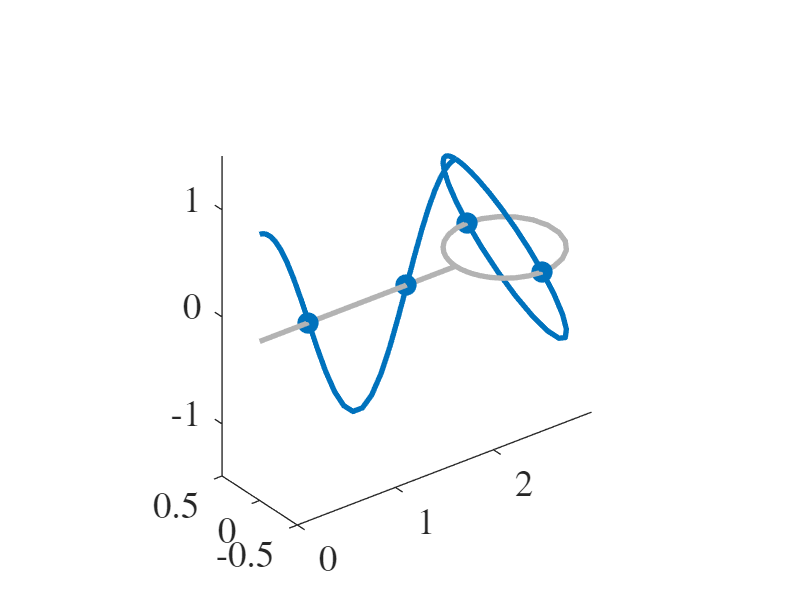

    exactSolution = Phi.applyFunctionsToAllEdges({u1,u2});

Set up the nonhomogeneous data on the edges

    edgeData = Phi.applyFunctionsToAllEdges({f1,f2});

The maximum error went down by a factor of 902.6630.


Solve and compute errors

    numericalSolution = Phi.solvePoisson('edgeData',edgeData)+1.5;
    errors(k)= max(abs(exactSolution-numericalSolution));
end

Plot the solution

Phi.plot(numericalSolution)

Plot the exact solution

Phi.plot(exactSolution)

Display the reduction in error. Since the discretization is second order, this should be about a faction of four.

fprintf("The maximum error went down by a factor of %0.4f.\n", errors(1)/errors(2) )
